Section 1

syms s k z p1 p2
Av = k*(s+z)/((s + p1) * (s + p2))

$$Av = \frac{k\,\left(s+z\right)}{\left(p_{1}+s\right)\,\left(p_{2}+s\right)}$$

k = 25; z = 7; p1 = 0.01; p2 = 200;
Av = subs(Av)

$$Av = \frac{25\,\left(s+7\right)}{\left(s+\frac{1}{100}\right)\,\left(s+200\right)}$$

Section 2 

[symNum, symDen] = numden(Av)

$$symNum = 2500\,s+17500$$

$$symDen = \left(100\,s+1\right)\,\left(s+200\right)$$

num = sym2poly(symNum)

num =         2500       17500


den = sym2poly(symDen)

den =          100       20001         200


AvTF = tf(num, den)

AvTF =
 
      2500 s + 17500
  -----------------------
  100 s^2 + 20001 s + 200
 
Continuous-time transfer function.
Model Properties


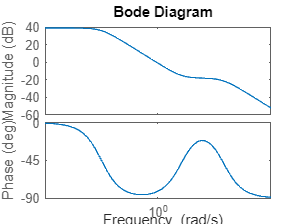

bode(AvTF)

Section 3 

opts = bodeoptions

opts =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
     

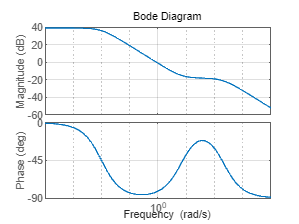

opts.Grid = 'on';
bode(AvTF, opts)


opts = bodeoptions

opts =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
     

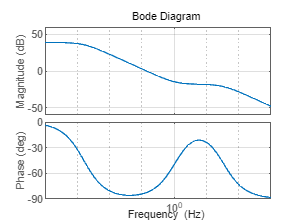

opts.Grid = 'on';
opts.XLim = [10^-4 10^3];
opts.YLim = {[-60 60], [-90 0]};
opts.FreqUnits = 'Hz';
bode(AvTF, opts)


opts = bodeoptions

opts =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
     

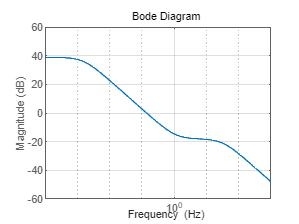

opts.Grid = 'on';
opts.PhaseVisible = 'off';
opts.XLim = [10^-4 10^3];
opts.YLim = {[-60 60], [-90 0]};
opts.FreqUnits = 'Hz';
bode(AvTF, opts)


syms s k z p1 p2
Av2 = k*(s+z)/(s + p1)

$$Av2 = \frac{k\,\left(s+z\right)}{p_{1}+s}$$

k = 8; z = 0.05; p1 = 3; 
Av2 = subs(Av2)

$$Av2 = \frac{8\,\left(s+\frac{1}{20}\right)}{s+3}$$


[symNum, symDen] = numden(Av2)

$$symNum = 40\,s+2$$

$$symDen = 5\,s+15$$

num = sym2poly(symNum)

num =     40     2


den = sym2poly(symDen)

den =      5    15


AvTF2 = tf(num, den)

AvTF2 =
 
  40 s + 2
  --------
  5 s + 15
 
Continuous-time transfer function.
Model Properties


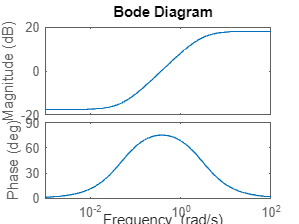

bode(AvTF2)


opts = bodeoptions

opts =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
     

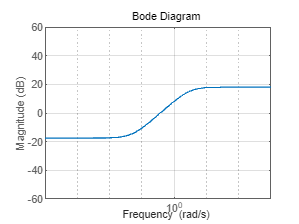

opts.Grid = 'on';
opts.PhaseVisible = 'off';
opts.XLim = [10^-4 10^3];
opts.YLim = {[-60 60], [-90 0]};
% opts.FreqUnits = 'Hz';
bode(AvTF2, opts)